# Discrete Time Filter Desing

## Filters Overview


$$\sum_{k=0}^N a_k y[n-k] =\sum_{k=0}^M b_k x[n-k]$$



$$Y(e^{j\omega}) = \frac{\sum_{k=0}^M b_k e^{-j\omega k }}{\sum_{k=n}^N a_k e_{-j\omega k}} X(e^{j\omega})$$


Discrete-time filters are divided into two categories,

- Finite impulse response (FIR): $h[n]=0$ for some $a$ and $b$ such that $-\infty<a<b<b<+\infty$

- Infinite impulse response (IIR): not FIR

Filters that can be described with difference-equations

- FIR: $N=0$

- IIR: $N>0$

- A simple FIR filter is the moving average filter.

- A simple IIR filter is the first order lowpass filter.

## Ideal Filters

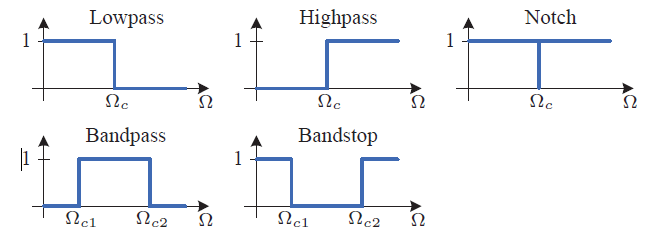

The cutoff frequencies must range between 0 and $\pi$.

## Practical Filters

Lowpass and highpass filters requirements

- Passband range

- Stopband range

- Maximum ripple in the passband

- Minimum attenuation in the stopband

There are four popular types of standard filters

- Butterworth

- Chebyshev Type I

- Chebyshe Type II

- Elliptic

## Ripple Tradeoff

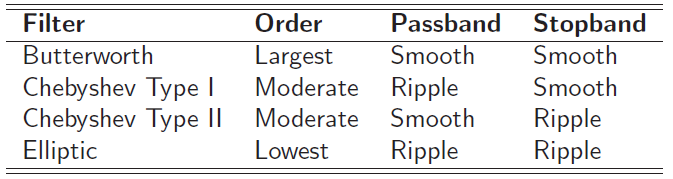

## Example 2: Lowpass Filter Specifications

Design a lowpass filter that meets the following specifications,

- The passband ripple is no more than 0.4455 dB

- The stopband attenuation is at least 26.02dB ($|H(e^{j\omega})| \le 0.05$)

- The passband ranges from 0 -$0.2\pi$rad/sample

- The stopband ranges from $0.3\pi$- $\pi$ rad/sample

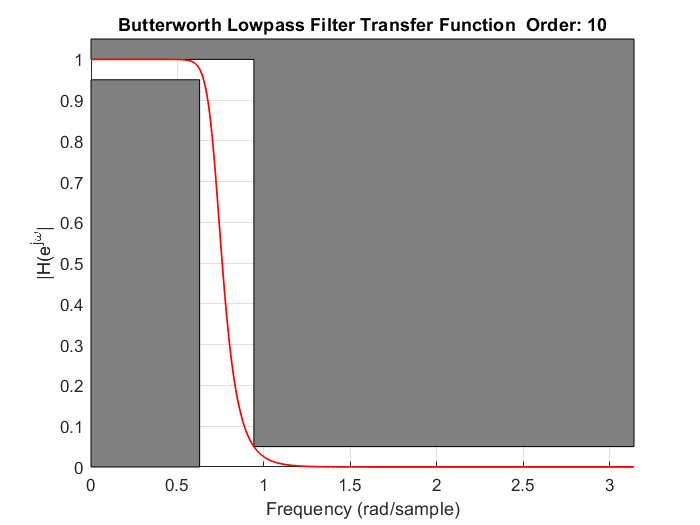

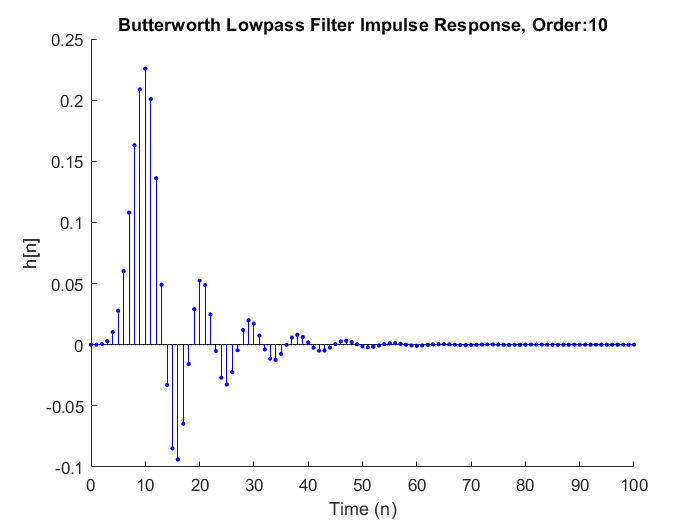

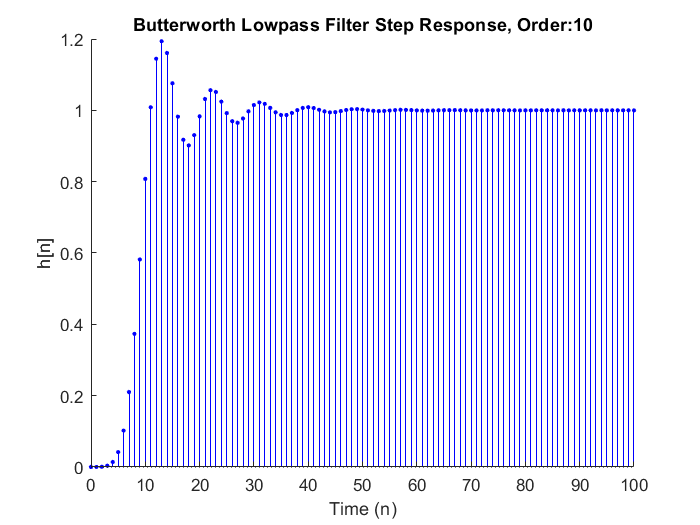

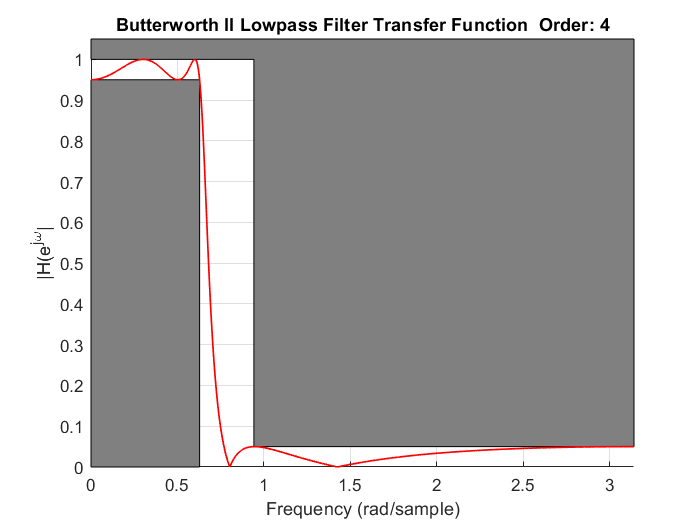

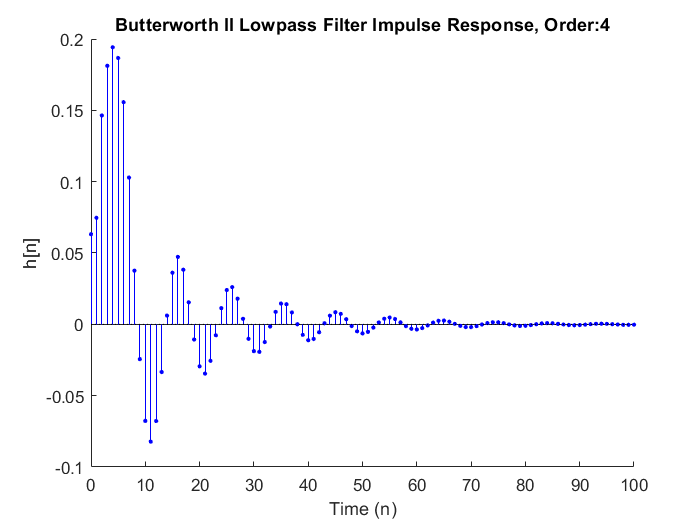

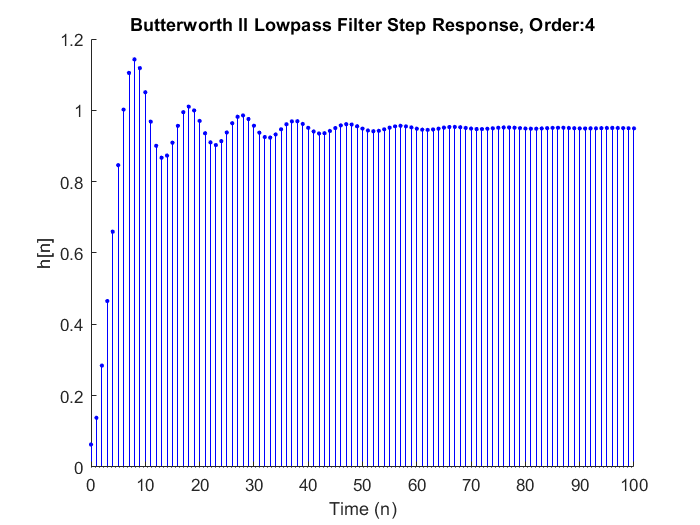

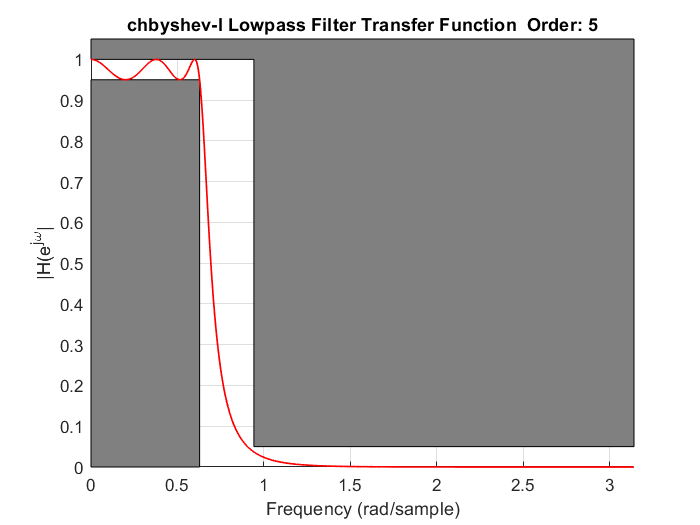

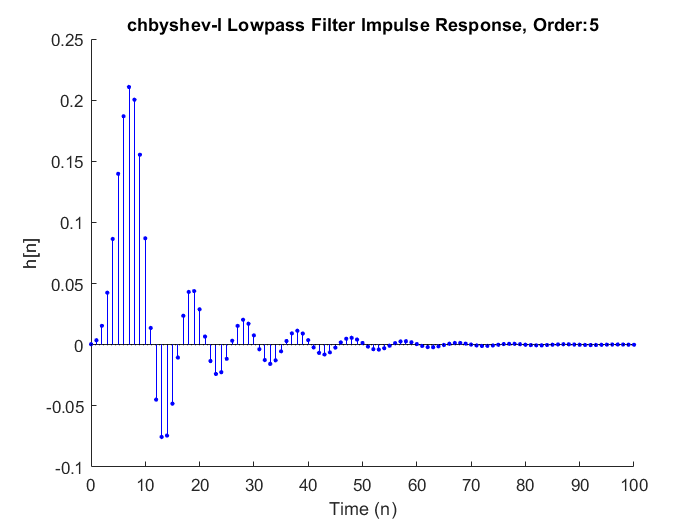

Wp = 0.2;                % Passband ends
Ws = 0.3;                % Stopband begins
Rp = -20*log10(0.95);    % Maximum deviation from 1 in the passband (dB)
Rs = -20*log10(0.05);    % Minimum attenuation in the stopband (dB)

for cnt = 1:4
    if cnt == 1
        [od, wn] = buttord(Wp, Ws, Rp, Rs);
        [B, A] = butter(od, wn);
        stFilter = 'Butterworth';
    elseif cnt == 2
        [od, wn] = ellipord(Wp, Ws, Rp, Rs);
        [B, A] = ellip(od, Rp, Rs, wn);
        stFilter = 'Butterworth II';
    elseif cnt == 3
        [od, wn] = cheb1ord(Wp, Ws, Rp, Rs);
        [B, A] = cheby1(od, Rp, wn);
        stFilter = 'chbyshev-I';
    elseif cnt == 4
        [od, wn] = cheb2ord(Wp, Ws, Rp, Rs);
        [B, A] = cheby2(od, Rs, wn);
        stFilter = 'chbyshev-II';
    else
        break;
    end;
    
    sys = tf(B, A, -1);
    wp = Wp * pi;
    ws = Ws * pi;
    
    ymax = 1.05;
    pbmax = 1;
    pbmin = 10^(-Rp/20);
    sbmax = 10^(-Rs/20);
    wmax = pi;
    w = 0:0.001:wmax;
    [H,w] = freqz(B, A, w);
    mag = abs(H);
    phs = angle(H);
    
    %% Plot magnitude on Linear Scale
    figure;
    hold on;
    h = patch([ 0 wp wp 0], [0 0 pbmin pbmin], 0.5*[1 1 1]);
    h = patch([0 ws ws wmax wmax 0], [pbmax pbmax sbmax sbmax ymax ymax], 0.5*[1 1 1]);
    set(h, 'LineWidth', 0.00001);
    h = plot(w, mag, 'r');
    set(h, 'LineWidth', 1);
    ylim([0 ymax]);
    xlim([0 wmax]);
    grid on;
    ylabel('|H(e^{j\omega}|');
    xlabel('Frequency (rad/sample)');
    title(sprintf('%s Lowpass Filter Transfer Function  Order: %d', stFilter, od));
    box off;
    
    %% Impulse Response
    figure;
    n = 0:100;
    [x, t] = impulse(sys, n);
    h = stem(t, x, 'b');
    set(h(1), 'MarkerFacecolor', 'b');
    set(h(1), 'Markersize', 2);
    ylabel('h[n]');
    xlabel('Time (n)');
    title(sprintf('%s Lowpass Filter Impulse Response, Order:%d', stFilter, od));
    box off;
    hold on;
    h = plot(xlim, [0 0], 'k:');
    hold off;
    
    %% Step Response
    figure;
    n = 0:100;
    [x, t] = step(sys, n);
    h = stem(t, x, 'b');
    set(h(1), 'MarkerFacecolor', 'b');
    set(h(1), 'Markersize', 2);
    ylabel('h[n]');
    xlabel('Time (n)');
    title(sprintf('%s Lowpass Filter Step Response, Order:%d', stFilter, od));
    box off;
    hold on;
    h = plot(xlim, [0 0], 'k:');
    hold off;

end

## First Order Lowpass and Highpass Filter (analog)

The cutoff frequency is $\omega_c$, the first order lowpass filter is,


$$H(s) = \frac{\omega_c}{s + \omega_c} = \frac{1}{1 + s/\omega_c}$$


clear;
fc = 1e3;
omega_c = 2 * pi * fc;
lpf_1st = tf([1], [1/omega_c, 1]);
hpf_1st = tf([1/omega_c, 0], [1/omega_c, 1]);

display(lpf_1st);


lpf_1st =
 
         1
  ---------------
  0.0001592 s + 1
 
Continuous-time transfer function.



display(hpf_1st);


hpf_1st =
 
    0.0001592 s
  ---------------
  0.0001592 s + 1
 
Continuous-time transfer function.



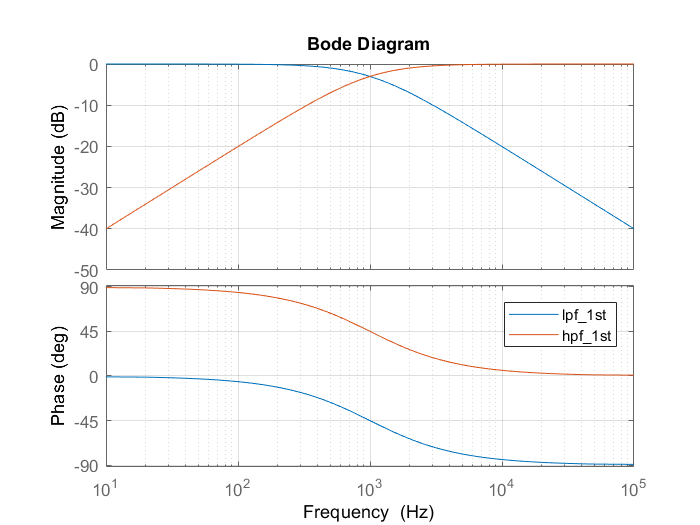

%% Plot magnitude on Linear Scale
figure;
hold on;
h_lpf_1st = bodeplot(lpf_1st);
setoptions(h_lpf_1st, 'FreqUnits','Hz');
grid on;
h_hpf_1st = bodeplot(hpf_1st);
setoptions(h_lpf_1st, 'FreqUnits','Hz');
legend('lpf\_1st', 'hpf\_1st');

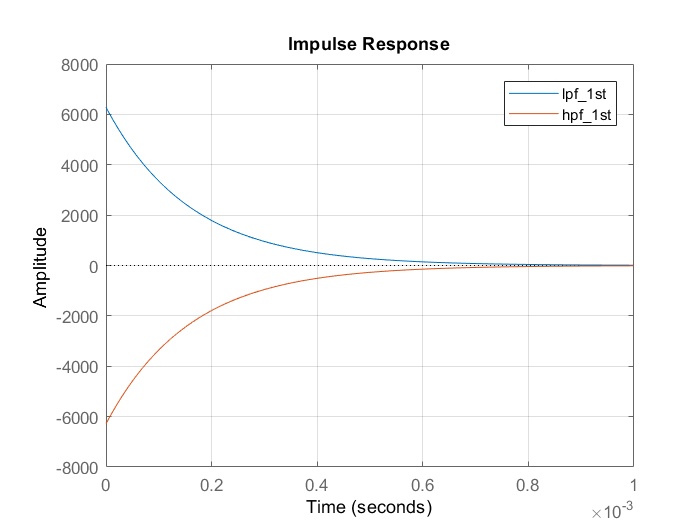

figure;
hold on;
h_impulse_lpf_1st = impulseplot(lpf_1st);
h_impulse_hpf_1st = impulseplot(hpf_1st);
grid('on');
legend('lpf\_1st', 'hpf\_1st');

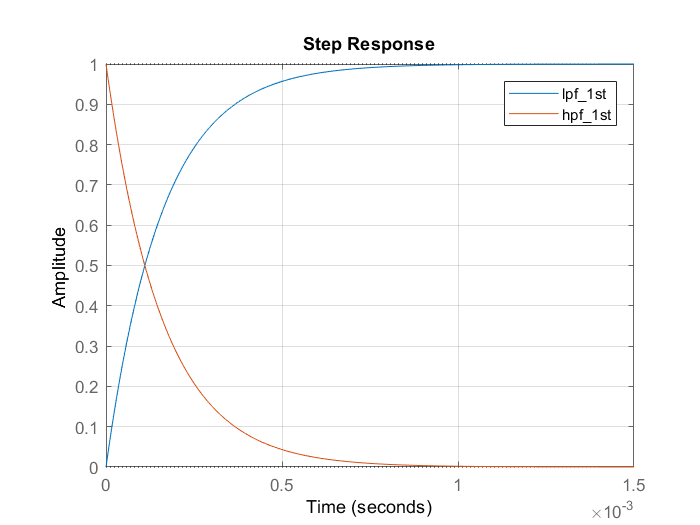

figure;
hold on;
h_step_lpf_1st = stepplot(lpf_1st);
h_step_hpf_1st = stepplot(hpf_1st);
grid on;
legend('lpf\_1st', 'hpf\_1st');

## Discretization of Lowpass Filter


$$H(s) =\frac{y(s)}{u(s)} = \frac{\omega_c}{s + \omega_c} = \frac{1}{1 + s/\omega_c} = \frac{1}{1+s T_f}$$


$\omega_c$ is the bandwidth. $T_f$ is the filter constant. 


$$(1+s T_f) y(s) = y(s) + s y(s) T_f= u(s)$$


In time domain after inverse Laplace transform, 


$$T_f \dot{y}(t) + y(t) = u(t)$$


Use $t_k$ to represent the present point of time — or discrete time:


$$T_f \dot{y}(t_k) + y(t_k) = u(t_k)$$


Apply Euler's backward differentiation approximation,


$$T_f \frac{y(t_k) - y(t_{k-1})}{T_s} + y(t_k) = u(t_k)$$


Solve $y(t_k)$ gives,


$$y(t_k) = (1 - a) y(t_{k-1}) + a u(t_k)$$


Where $a = \frac{T_s}{T_f + T_s}$, usually $T_s \le \frac{T_f}{5}$ to guarantee that the discrete filter functions similar to the analog one. 

This filter is denoted the **exponentially weighted moving average (EWMA) filter**.

## Seconda Order Filters

Second order filters are filters with a denominator polynomial that is of second order.

It's also the building blocks for higher-order filters.

## Standard Form


$$H(s) = \frac{N(s)}{\frac{s^2}{{\omega_n}^2} + \frac{s}{Q\cdot \omega_n} + 1}$$


The roots (poles) are usually complex,


$$p_{1,2} = -\zeta \omega_n \pm j \omega_n \sqrt{1- \zeta^2}$$


Second order filters can be designed as lowpass, highpass, bandpass, or notch filters. All four types can be expressed in standard form shown above.

- If $N(s) = k$, the system is a lowpass filter with a DC gain of $k$.

- if $N(s) = k \frac{s^2}{\omega_n ^2}$, the system is a highpass filter with a high frequency gain of $k$.

- If $N(s) =k \frac{s}{Q \omega_n}$, the system is a bandpass filter with a maximum gain of $k$. 

- If $N(s) = k\left(1 - \frac{s^2}{\omega_n^2}\right)$, the system is a notch filter with a gain of $k$.

## Unity Gain Lowpass

When $N(s)=1$, it's unity gain lowpass filter. 

It can be rewrite as, 


$$H(s) = \frac{1}{\frac{s^2}{{\omega_n}^2} + \frac{s}{Q\cdot \omega_n} + 1}
=\frac{1}{\frac{s^2}{{\omega_n}^2} + 2\zeta \frac{s}{\omega_n} + 1}
=\frac{\omega_n^2}{s^2 + 2\zeta \omega_n s+\omega_n^2}$$


- $\omega_n$ is called the `undamped natural frequency`.

- $\zeta$ is called the `damping ratio`. 

- The polse are $p_{1,2} = \left(-\zeta \pm \sqrt{\zeta^2 - 1} \right) \omega_n$

- If $\zeta\ge1$, the poles are real

- If $0<\zeta<1$, the poles are complex

- If $\zeta = 0$, the poles are imaginary: $p_{1,2}=\pm j \omega_n$

- If $\zeta < 0$, the poles are in the right half plane ( $Re(p)>0$) and the system is unstable.

The relationship of damping ratio and quality factor is,


$$Q = \frac{1}{2\zeta}$$


The unity gain lowpass filter in Fourier domain is,


$$H(j\omega) = \frac{1}{1- \left(\frac{\omega}{\omega_n}\right)^2 + \frac{j\omega}{Q \omega_n}$$


Unity Gain Lowpass Filter **Magnitude Response**, 


$$20 \log_{10} \left |H(j\omega)\right|
=20 \log_{10} \left |\frac{1}{1- \left(\frac{\omega}{\omega_n}\right)^2 + \frac{j\omega}{Q \omega_n}}\right|
=-20 \log_{10} \sqrt{\left(1- \frac{\omega^2}{\omega_n^2}\right)^2 + \frac{\omega^2}{Q^2 \omega_n^2}}$$


- For $\omega\ll \omega_n$, $20 \log_{10} \left |H(j\omega)\right| \approx-20 \log_{10}|1| =0dB$

- For $\omega\gg \omega_n$, $20 log_{10} \left |H(j\omega)\right| \approx-20 \log_{10} \frac{\omega^2}{\omega_n^2} = - 40 \log_{10} \frac{\omega}{\omega_n} dB$

- For $\omega = \omega_n$, $20 log_{10} \left |H(j\omega)\right| 
\approx -20 \log_{10} \frac{1}{Q} 
= 20 \log_{10} {Q} = Q_{dB}$

Unity Gain Lowpass Filter **Phase Response**,


$$\angle H(j\omega) = \angle \frac{1}{1-\left(\frac{\omega}{\omega_n}\right)^2 + \frac{j\omega}{Q \omega_n}}$$


- For $\omega \ll \omega_n$, $\angle H(j\omega) \approx \angle 1 = 0^\circ$

- For $\omega \gg \omega_n$, $\angle H(j\omega) \approx \angle \frac{1}{-\frac{\omega}{Q \omega_n}} =\angle -\frac{Q\omega_n}{\omega}=\angle -1 = -180^\circ$

- For $\omega=\omega_n$, $\angle H(j\omega) \approx \frac{1}{Qj} = \angle -j = -90^\circ$

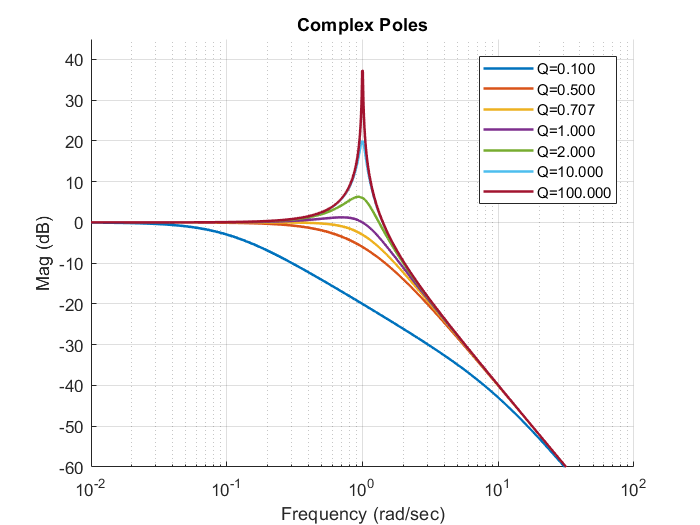

clear;
N = 1000;
wn = 1;
Q = [0.1 0.5 sqrt(1/2) 1 2 10 100];
w = logspace (-2,2,N);
nQ = length(Q);
mag = [];
phs = [];
legendLabels = cell(nQ ,1);
for c1 = 1: nQ
    sys = tf ([ wn ^2] ,[1 wn/Q(c1) wn ^2]);
    [m, p] = bode (sys ,w);
    mag = [ mag reshape(m,N,1)];
    phs = [ phs reshape(p,N,1)];
    legendLabels {c1} = sprintf('Q=%5.3f',Q(c1));
end

figure;
h = semilogx(w ,20* log10(mag ));
set(h,'LineWidth' ,1.5 );
grid on;
xlabel('Frequency (rad/sec)');
ylabel('Mag (dB)');
title('Complex Poles');
xlim ([w(1) w( end )]);
ylim ([ -60 45]);
box off;
legend( legendLabels );
print(' BodeMagComplexPoles','-depsc');

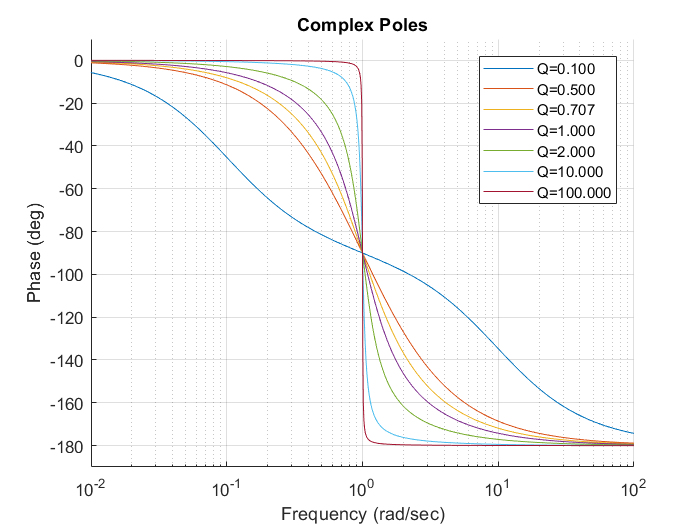

figure;
semilogx(w,phs);
set (gca, 'Xscale', 'log')
set(h,'LineWidth' ,1.5 );
grid on;
xlabel('Frequency (rad/sec)');
ylabel('Phase (deg)');
title('Complex Poles');
xlim ([w(1) w(end)]);
ylim ([ -190 10]);
box off;
legend( legendLabels );
print(' BodePhaseComplexPoles','-depsc');

Some comments,

- The second-order response attenuates twice as fast as a first-order response (40 dB/decade)

- Generally better than the cascade of two first-order filters

- Offers additional degree of freedom (Q), which is the gain near $\omega=\omega_n$

- Q may range from 0.5 to 100, but is usually near Q = 1

For high values of $Q$, the maximum of $|H(j\omega)| > 1$, it's called **peaking**. The largest Q before the onset of peaking is $Q=\frac{1}{\sqrt 2} \approx 0.707$

- Said to be **maximally flat**

- Also called a **Butterworth response**

- In this case, $|H(j\omega_n)| = -3 dB$ and $\omega_n$ is the cutoff frequency

If $Q > 0.707$, the maximum magnitude and frequency are as follows:

$\omega_r = \omega_n \sqrt{1 - \frac{1}{2Q^2}}$, $|H(j\omega_r)| = \frac{Q}{1 - \frac{1}{4Q^2}}$

- $\omega_r$ is called the **resonant frequency** or the **dampled natural frequency**.

- As $Q \to \infty$, $\omega_r \to \omega_n$, for sufficiently large $Q$ (i.e, $Q>5$)

- --> $\omega_r \approx \omega_n$

- --> $|H(j\omega_r)| \approx Q$